# Plotting

## The basics of line plots

For more info, see [this page.](https://www.mathworks.com/help/matlab/line-plots.html?s_tid=CRUX_lftnav)

To plot the graph of a function, you need to take the following steps:

- Define x, by specifying the range of values for the variable x, for which the function is to be plotted

- Define the function, y = f(x)

- Call the plot command, as plot(x, y)

Let's start with a simple example of a line. Note the use of the figure command, which opens a new figure window. Though this isn't always necessary, I always do this in case the setting for plotting on the same axes is on (see below).

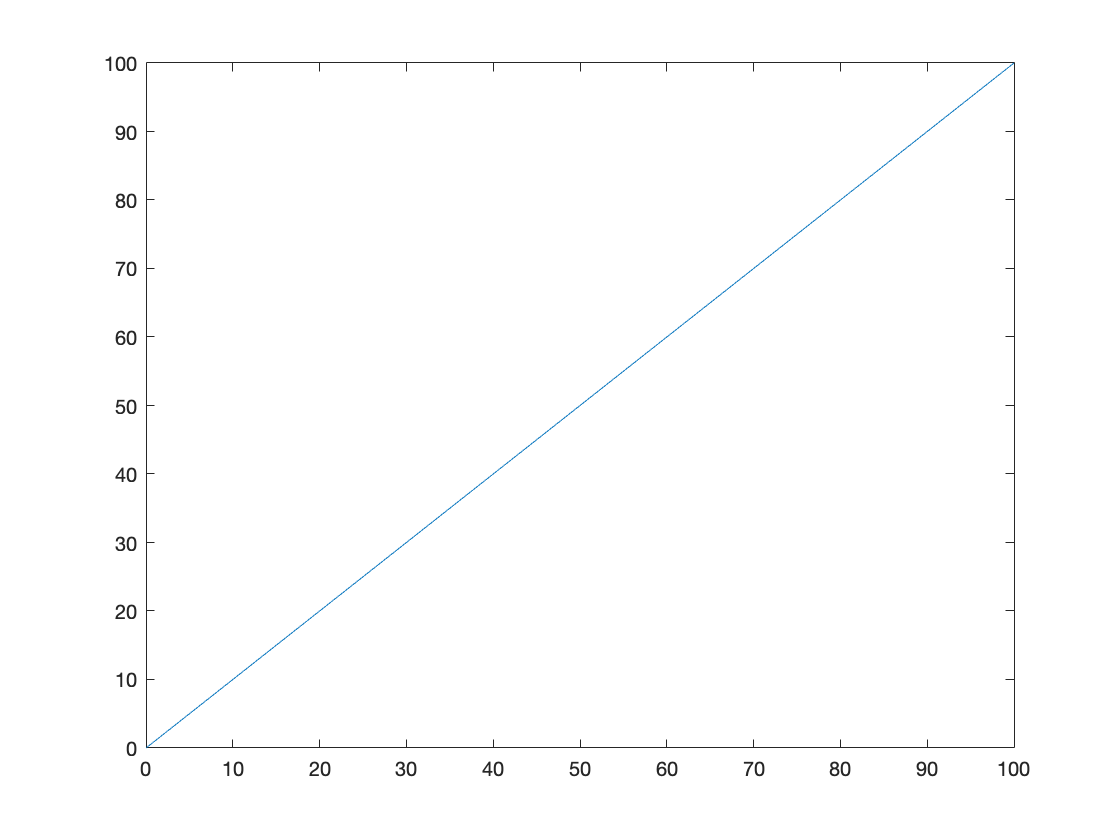

figure
x = 0:5:100;
y = x;
plot(x, y)

Now let's plot a parabola. Try changing the minimum value, maximum value, and increment specified in the range. What happens when you decrease the incremement?

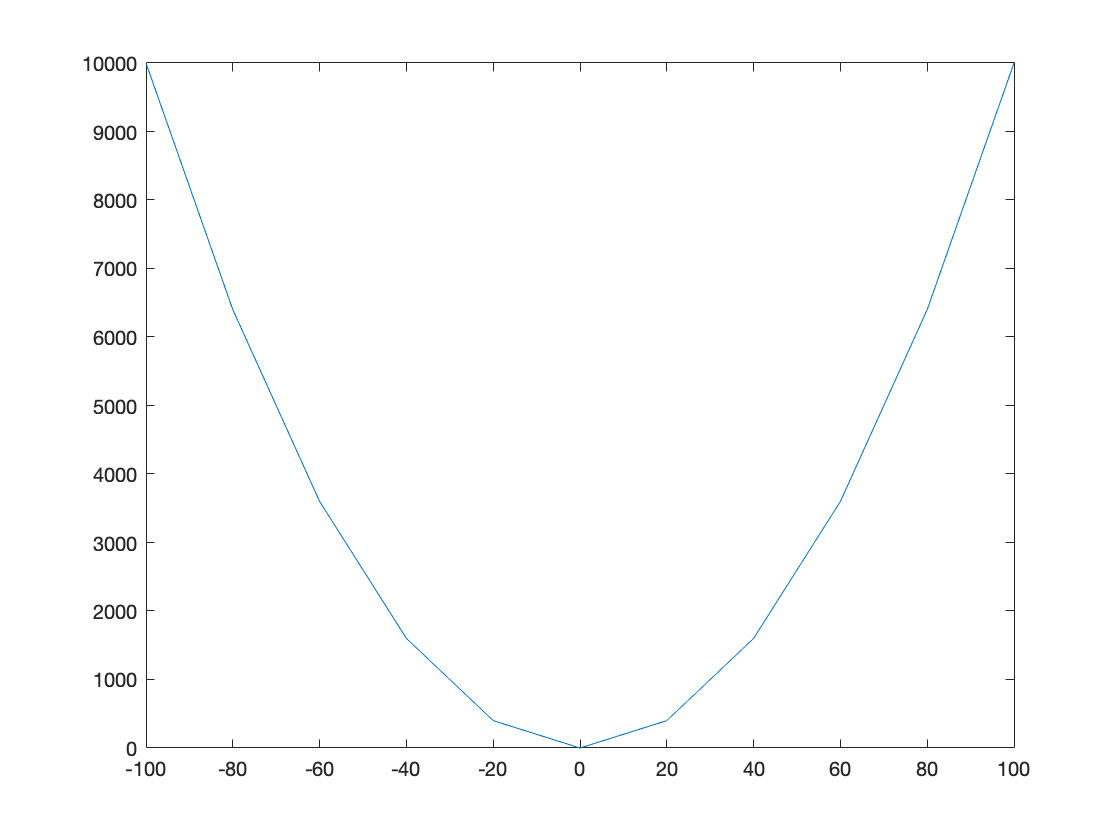

figure
x = -100:20:100;
y = x.^2;
plot(x, y)

Though colon notation is perfectly fine, another handy function is linspace(). `linspace(x1, x2, n)` generates `n` evenly-spaced points between x1 and x2. (If you don't specify n, a default of 50 is used.) We can reproduce the same range of x from above with the following code, though ideally we'd make n something like 100 to increase the "resolution" of our graph.

x = linspace(-100,100,11)

x =   -100   -80   -60   -40   -20     0    20    40    60    80   100


## Adding Title, Labels, Grid Lines and Scaling on the Graph

MATLAB allows you to add title, labels along the x-axis and y-axis, grid lines and also to adjust the axes to spruce up the graph.

- The xlabel and ylabel commands generate labels along x-axis and y-axis.

- The title command allows you to put a title on the graph.

- The grid on command allows you to put the grid lines on the graph.

- The axis equal command allows generating the plot with the same scale factors and the spaces on both axes.

- The axis square command generates a square plot.

Let's make a plot of the sine function with some of these features.

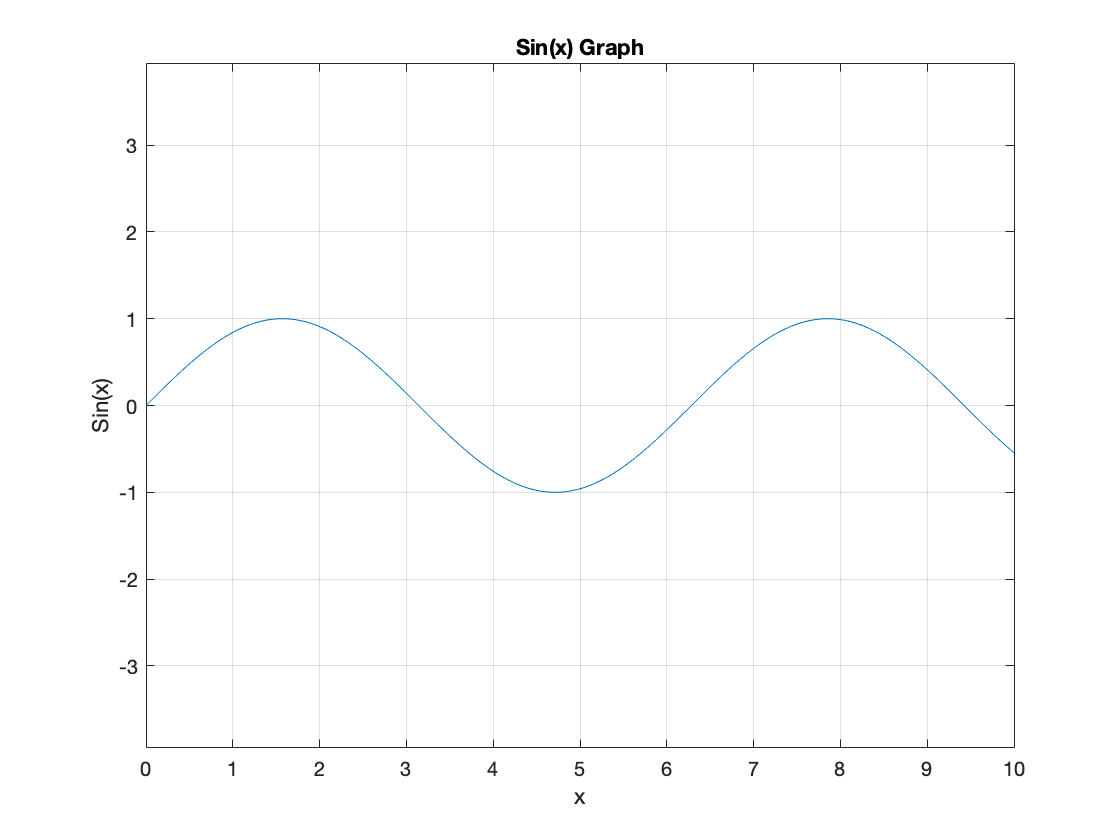

figure
x = 0:0.01:10;
y = sin(x);

plot(x, y)
xlabel('x')
ylabel('Sin(x)')
title('Sin(x) Graph'),
grid on, axis equal

## Drawing Multiple Functions on the Same Graph

You can also draw multiple graphs on the same plot. There are several ways to do this, but I recommend options 2 and 3 because they are convenient when handling more data (especially 2), iteratively plotting data (especially 3), etc.

#### Option 1

One way is to simply list each dependent and independent variable vector in order as arguments to the plot function, as below.

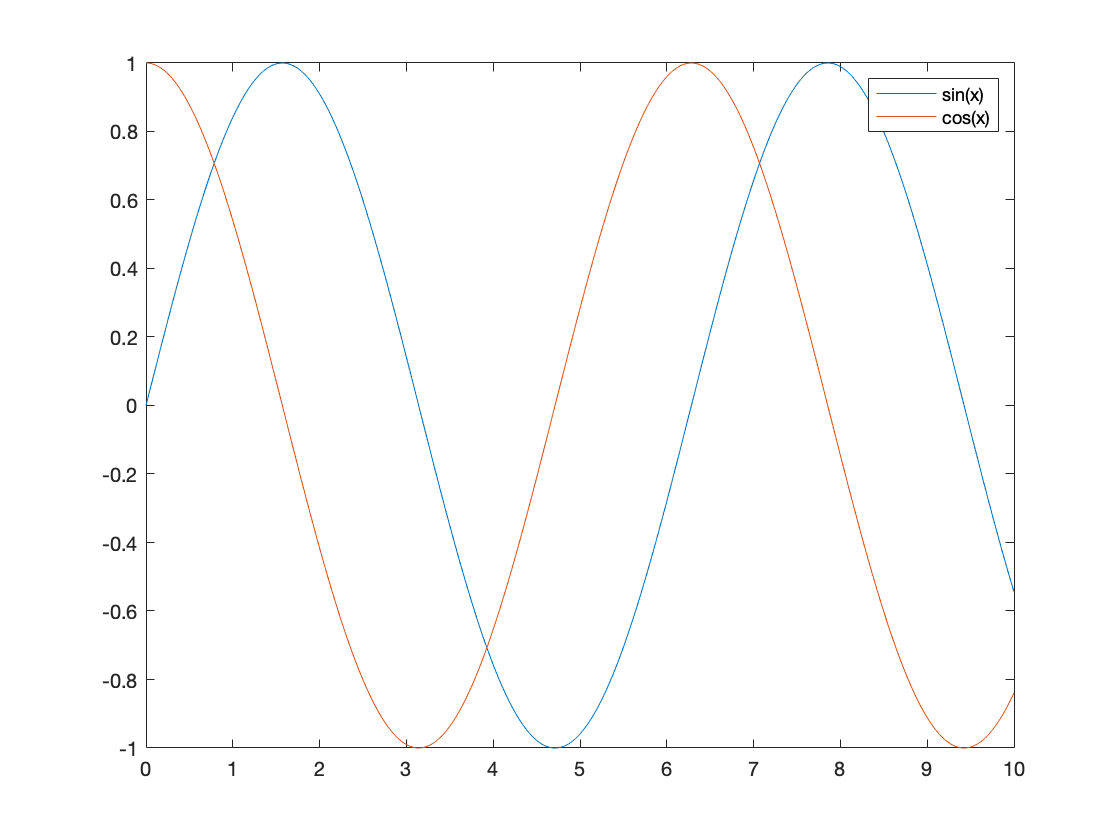

figure
x = 0:0.01:10;
y_sin = sin(x);
y_cos = cos(x);

plot(x, y_sin, x, y_cos)
legend('sin(x)', 'cos(x)')

#### Option 2

Another option is to input matrices rather than vectors to the plot function, where each column in Y is plotted against the corresponding column in X as a new line.

figure
X = [x', x'];
Y = [y_sin', y_cos'];

% Fancy alternatives, useful when working with more data
% X = repmat(x', 1, 2);
% Y = cat(2, y_sin', y_cos');

plot(X, Y)
legend('sin(x)', 'cos(x)')

#### Option 3

The last way we'll discuss is using the hold on command. After using this command, anything you plot will be added to the existing axes.

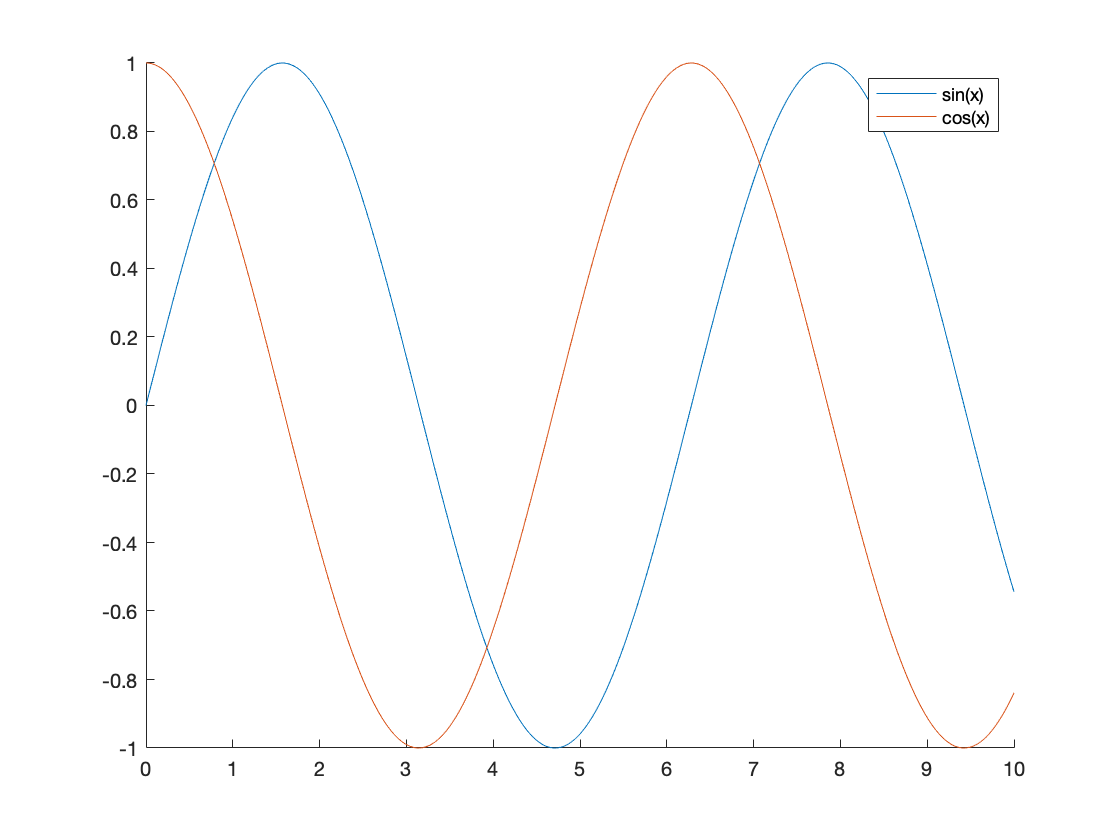

figure
hold on

plot(x, y_sin)
plot(x, y_cos)

legend('sin(x)', 'cos(x)')

## Setting linestyle and colors

See [this page](https://www.mathworks.com/help/matlab/creating_plots/specify-line-and-marker-appearance-in-plots.html) for more info on linestyle and markers.

Most line plots display a solid line by default, but you can customize the line with any of the line styles in the table on the page linked above. For example, we can modify our plots above to have dashed and dotted lines, or change the line width.

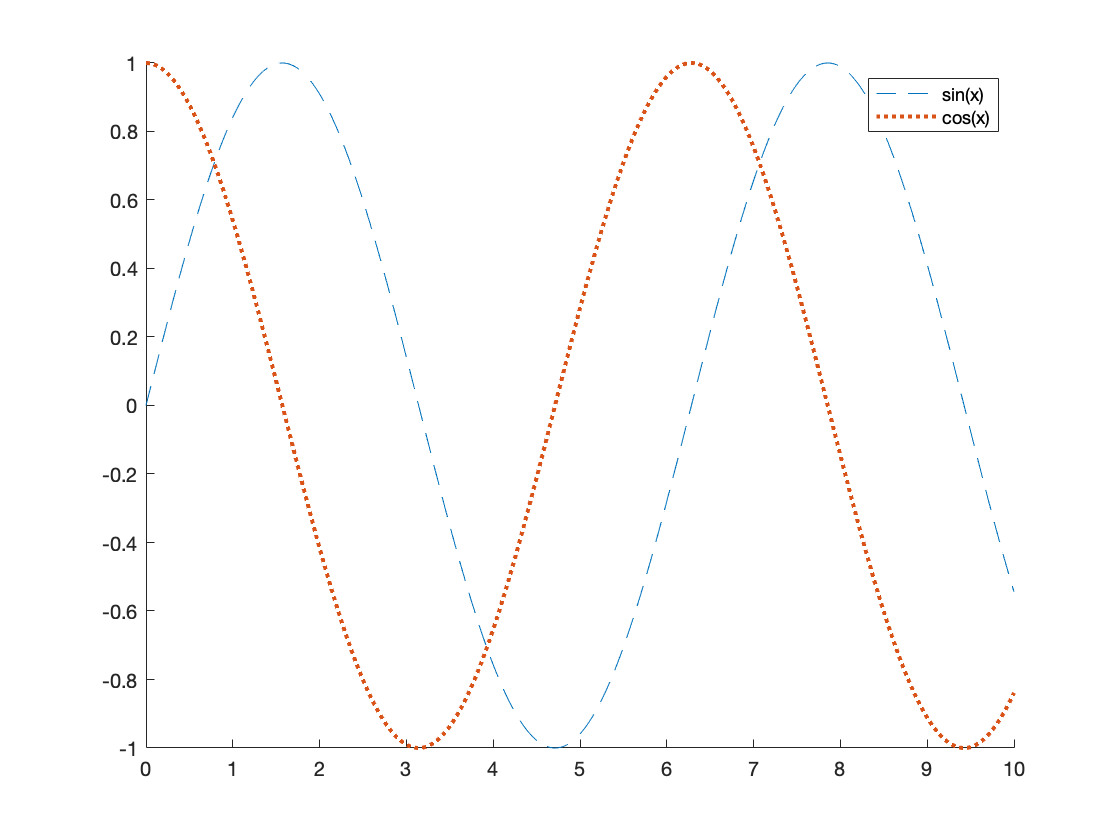

figure
hold on

plot(x, y_sin, '--')
plot(x, y_cos, ':', 'LineWidth', 2)

legend('sin(x)', 'cos(x)')

In the case above, we wouldn't want to use markers since we have so many points. However, when your points are sparser and you want to highlight them, markers can come in handy. You can include them when specifying your linestyle. More markers are shown on the page linked above.

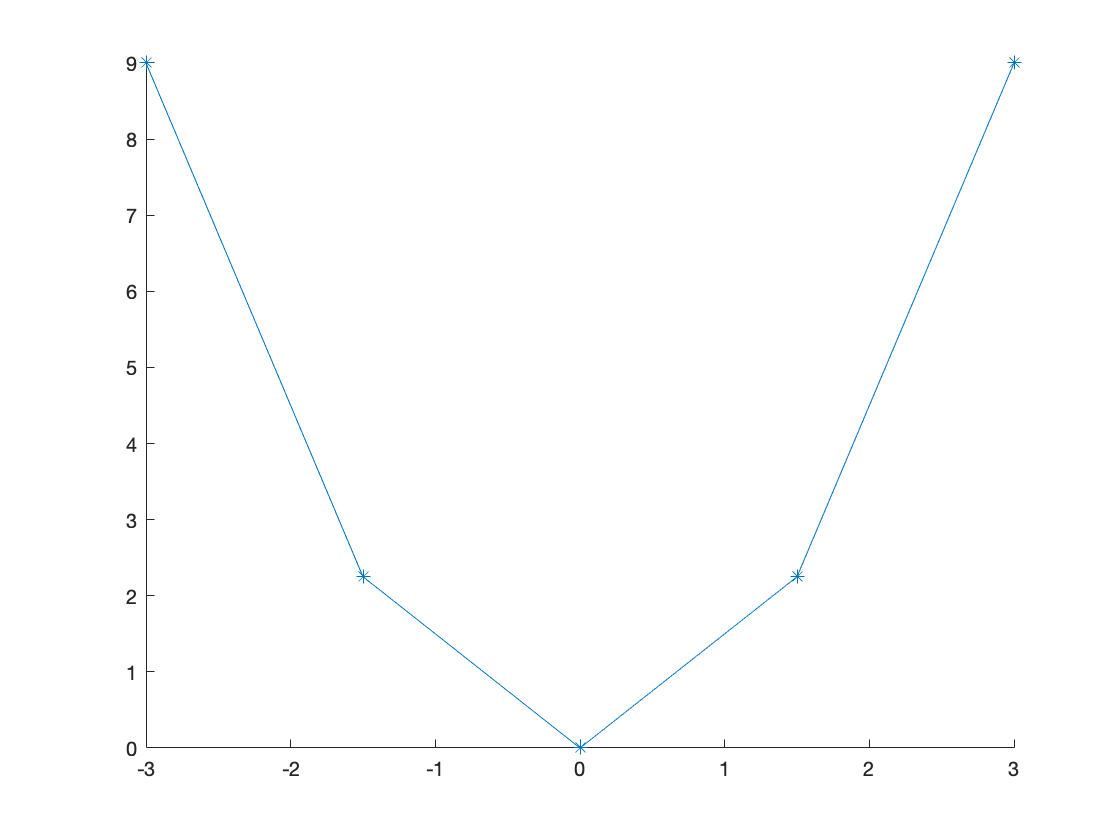

figure
hold on

x = linspace(-3, 3, 5);
y = x .^ 2;

plot(x, y, '-*')

Now let's customize the color. We'll use a "ready-made" color, which can be included in the linestyle specification, and an RGB color, which needs to be specified separately.

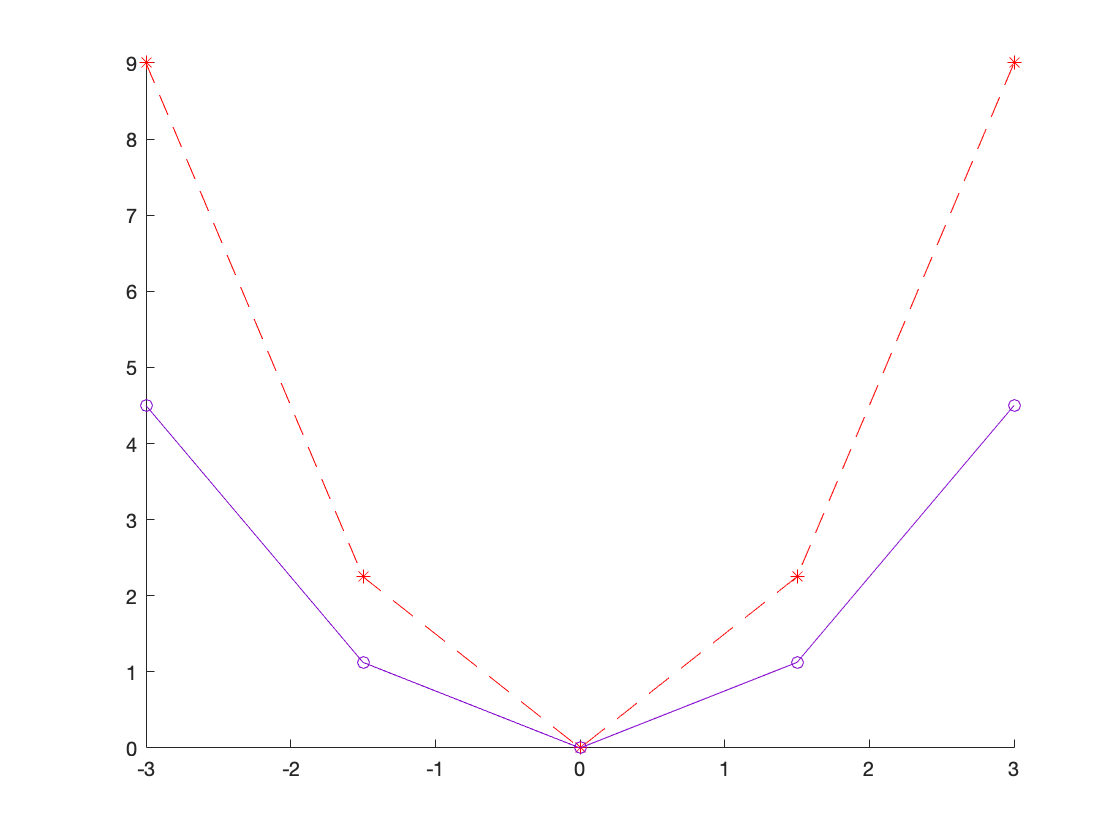

figure
hold on

x = linspace(-3, 3, 5);
y1 = x .^ 2;
y2 = 0.5 * (x .^ 2);

plot(x, y1, '--*r')
plot(x, y2, '-o', 'Color', [0.5 0 0.8])

## Coding challenge

Now it's your turn! Recreate (with some room for creativity) the figure below, adhering to the following steps:

- Assign the number of lines to a variable.

- Create a vector x that will serve as your x range. Using [linspace()](https://www.mathworks.com/help/matlab/ref/linspace.html), make your x range have a maximum of 5, a minimum of -5, and contain 100 evenly-spaced points.

- Using the [repmat()](https://www.mathworks.com/help/matlab/ref/repmat.html) function, create a matrix X of dimension (length x) by (# lines), where each column is a copy of x.

- Using a for loop, create a matrix Y of dimension (length x) by (# lines), where each column is the square root of x times the iteration index. Remember to use the component-wise operator!

- Plot Y versus X, using any line style you like.

- Add a title and labels for the x and y axes. Increase the font size of each using the 'FontSize' argument.

- Change the x-ticks and y-ticks using the [xticks()](https://www.mathworks.com/help/matlab/ref/xticks.html) and [yticks()](https://www.mathworks.com/help/matlab/ref/yticks.html) functions.

- Optional: At the beginning of your code, create an empty cell array of dimension (1) by (# lines) called labels. Inside your for loop, fill each entry of labels with a label dependent on the iteration index. Hint: use [string/character vector concatenation](https://www.mathworks.com/help/matlab/ref/strcat.html) and [num2str()](https://www.mathworks.com/help/matlab/ref/num2str.html). After plotting Y vs X, call legend(labels).

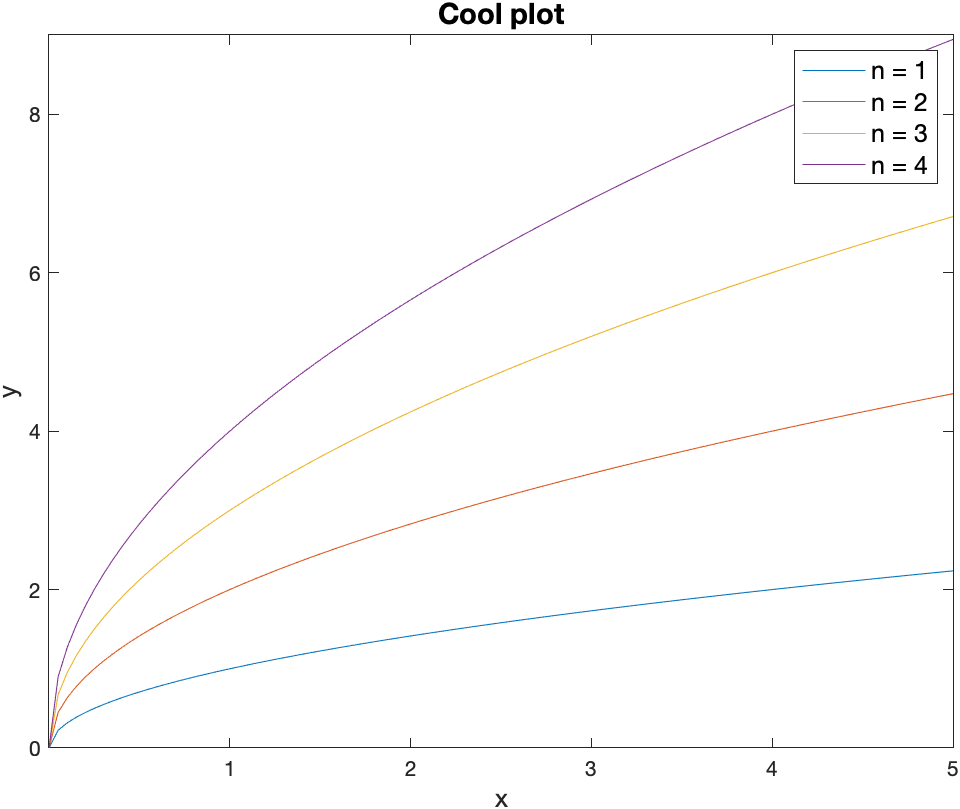

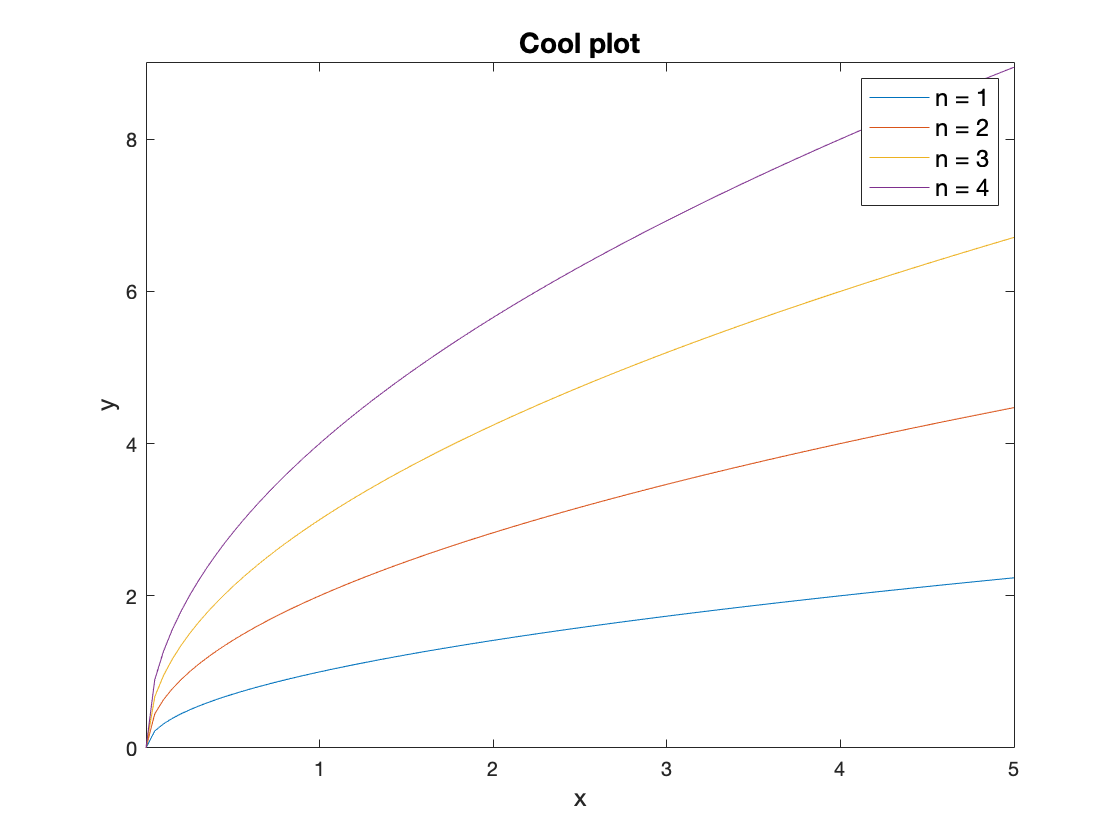

% Your code here
